% load data from the following dataset:
% /Volumes/yaochen/Active/Pingchuan/2022Fall/20221024_AchsensorHEK004
% 20221024_AchsensorHEK004 baseline of Tio collection

savedData = load('lifetime_collection_offset0.mat')

savedData = struct with fields:
          offset: 0
       fixoffset: 1
        Acq_nums: [45×1 double]
            lfts: [45×1 double]
    TruncEmpLfts: [45×1 double]
         photons: [45×1 double]
    photons_mean: [45×1 double]
    roiPositions: {1×45 cell}
             Acq: 25
            Acqs: 25
          ROInum: 1


lft_roi_recollection = [];

for i=1:length(savedData.Acq_nums)

    if savedData.Acq_nums(i)<10
        acqn_file = [gui.gy.filename.base 'FLIM00' num2str(savedData.Acq_nums(i)) '.mat'];
    else
        acqn_file = [gui.gy.filename.base 'FLIM0' num2str(savedData.Acq_nums(i)) '.mat'];
    end
    spc_openCurves(acqn_file)
    
    gui.gy.roiPositions = {};
    gui.gy.roiPositions{1} = savedData.roiPositions{i};
    coordinates_x = savedData.roiPositions{i}(:,1);
    coordinates_y = savedData.roiPositions{i}(:,2);
    gui.gy.rois{1}.mask = poly2mask(coordinates_x, coordinates_y, 128, 128);

    spc_calculateROIvals(0)
    lft_roi_recollection(i) = gui.gy.ROIlife;

    createdMask = boundarymask(gui.gy.rois{1}.mask);

    B = imoverlay(spc.rgbLifetimes{1}, createdMask);
    f = figure('visible','off')
    image(B)
    title(['baseline_', num2str(i),'_', num2str(savedData.Acq_nums(i)), '_', num2str(lft_roi_recollection(i))])
    image_name = ['baseline',num2str(i),'.png']
    saveas(f, image_name)
end

Reading 20221024_AchsensorHEK004FLIM001.mat


f =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline1.png'

Reading 20221024_AchsensorHEK004FLIM001.mat


f =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline2.png'

Reading 20221024_AchsensorHEK004FLIM001.mat


f =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline3.png'

Reading 20221024_AchsensorHEK004FLIM002.mat


f =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline4.png'

Reading 20221024_AchsensorHEK004FLIM003.mat


f =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline5.png'

Reading 20221024_AchsensorHEK004FLIM004.mat


f =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline6.png'

Reading 20221024_AchsensorHEK004FLIM004.mat


f =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline7.png'

Reading 20221024_AchsensorHEK004FLIM005.mat


f =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline8.png'

Reading 20221024_AchsensorHEK004FLIM005.mat


f =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline9.png'

Reading 20221024_AchsensorHEK004FLIM005.mat


f =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline10.png'

Reading 20221024_AchsensorHEK004FLIM006.mat


f =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline11.png'

Reading 20221024_AchsensorHEK004FLIM006.mat


f =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline12.png'

Reading 20221024_AchsensorHEK004FLIM006.mat


f =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline13.png'

Reading 20221024_AchsensorHEK004FLIM007.mat


f =   Figure (17) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline14.png'

Reading 20221024_AchsensorHEK004FLIM007.mat


f =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline15.png'

Reading 20221024_AchsensorHEK004FLIM007.mat


f =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline16.png'

Reading 20221024_AchsensorHEK004FLIM008.mat


f =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline17.png'

Reading 20221024_AchsensorHEK004FLIM008.mat


f =   Figure (21) with properties:

      Number: 21
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline18.png'

Reading 20221024_AchsensorHEK004FLIM008.mat


f =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline19.png'

Reading 20221024_AchsensorHEK004FLIM010.mat


f =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline20.png'

Reading 20221024_AchsensorHEK004FLIM010.mat


f =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline21.png'

Reading 20221024_AchsensorHEK004FLIM011.mat


f =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline22.png'

Reading 20221024_AchsensorHEK004FLIM011.mat


f =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline23.png'

Reading 20221024_AchsensorHEK004FLIM012.mat


f =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline24.png'

Reading 20221024_AchsensorHEK004FLIM012.mat


f =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline25.png'

Reading 20221024_AchsensorHEK004FLIM013.mat


f =   Figure (29) with properties:

      Number: 29
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline26.png'

Reading 20221024_AchsensorHEK004FLIM013.mat


f =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline27.png'

Reading 20221024_AchsensorHEK004FLIM014.mat


f =   Figure (31) with properties:

      Number: 31
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline28.png'

Reading 20221024_AchsensorHEK004FLIM015.mat


f =   Figure (32) with properties:

      Number: 32
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline29.png'

Reading 20221024_AchsensorHEK004FLIM015.mat


f =   Figure (33) with properties:

      Number: 33
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline30.png'

Reading 20221024_AchsensorHEK004FLIM016.mat


f =   Figure (34) with properties:

      Number: 34
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline31.png'

Reading 20221024_AchsensorHEK004FLIM016.mat


f =   Figure (35) with properties:

      Number: 35
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline32.png'

Reading 20221024_AchsensorHEK004FLIM017.mat


f =   Figure (36) with properties:

      Number: 36
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline33.png'

Reading 20221024_AchsensorHEK004FLIM018.mat


f =   Figure (37) with properties:

      Number: 37
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline34.png'

Reading 20221024_AchsensorHEK004FLIM020.mat


f =   Figure (38) with properties:

      Number: 38
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline35.png'

Reading 20221024_AchsensorHEK004FLIM020.mat


f =   Figure (39) with properties:

      Number: 39
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline36.png'

Reading 20221024_AchsensorHEK004FLIM020.mat


f =   Figure (40) with properties:

      Number: 40
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline37.png'

Reading 20221024_AchsensorHEK004FLIM022.mat


f =   Figure (41) with properties:

      Number: 41
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline38.png'

Reading 20221024_AchsensorHEK004FLIM022.mat


f =   Figure (42) with properties:

      Number: 42
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline39.png'

Reading 20221024_AchsensorHEK004FLIM023.mat


f =   Figure (43) with properties:

      Number: 43
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline40.png'

Reading 20221024_AchsensorHEK004FLIM023.mat


f =   Figure (44) with properties:

      Number: 44
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline41.png'

Reading 20221024_AchsensorHEK004FLIM023.mat


f =   Figure (45) with properties:

      Number: 45
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline42.png'

Reading 20221024_AchsensorHEK004FLIM024.mat


f =   Figure (46) with properties:

      Number: 46
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline43.png'

Reading 20221024_AchsensorHEK004FLIM024.mat


f =   Figure (47) with properties:

      Number: 47
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline44.png'

Reading 20221024_AchsensorHEK004FLIM025.mat


f =   Figure (48) with properties:

      Number: 48
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'baseline45.png'

savedData = load('lifetime_collection_offset0.mat')

savedData = struct with fields:
          offset: 0
       fixoffset: 1
        Acq_nums: [33×1 double]
            lfts: [33×1 double]
    TruncEmpLfts: [33×1 double]
         photons: [33×1 double]
    photons_mean: [33×1 double]
    roiPositions: {1×33 cell}
             Acq: 23
            Acqs: [2×1 double]
          ROInum: 2


lft_roi_recollection = [];

for i=1:length(savedData.Acq_nums)

    if savedData.Acq_nums(i)<10
        acqn_file = [gui.gy.filename.base 'FLIM00' num2str(savedData.Acq_nums(i)) '.mat'];
    else
        acqn_file = [gui.gy.filename.base 'FLIM0' num2str(savedData.Acq_nums(i)) '.mat'];
    end
    spc_openCurves(acqn_file)
    
    gui.gy.roiPositions = {};
    gui.gy.roiPositions{1} = savedData.roiPositions{i};
    coordinates_x = savedData.roiPositions{i}(:,1);
    coordinates_y = savedData.roiPositions{i}(:,2);
    gui.gy.rois{1}.mask = poly2mask(coordinates_x, coordinates_y, 128, 128);

    spc_calculateROIvals(0)
    lft_roi_recollection(i) = gui.gy.ROIlife;

    createdMask = boundarymask(gui.gy.rois{1}.mask);

    B = imoverlay(spc.rgbLifetimes{1}, createdMask);
    f = figure('visible','off')
    image(B)
    title(['Tio ', num2str(i),' ', num2str(savedData.Acq_nums(i)), ' ', num2str(lft_roi_recollection(i))])
    image_name = ['Tio',num2str(i),'.png']
    saveas(f, image_name)
end

Reading 20221024_AchsensorHEK006FLIM001.mat


f =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio1.png'

Reading 20221024_AchsensorHEK006FLIM001.mat


f =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio2.png'

Reading 20221024_AchsensorHEK006FLIM001.mat


f =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio3.png'

Reading 20221024_AchsensorHEK006FLIM003.mat


f =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio4.png'

Reading 20221024_AchsensorHEK006FLIM003.mat


f =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio5.png'

Reading 20221024_AchsensorHEK006FLIM003.mat


f =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio6.png'

Reading 20221024_AchsensorHEK006FLIM004.mat


f =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio7.png'

Reading 20221024_AchsensorHEK006FLIM004.mat


f =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio8.png'

Reading 20221024_AchsensorHEK006FLIM004.mat


f =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio9.png'

Reading 20221024_AchsensorHEK006FLIM005.mat


f =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio10.png'

Reading 20221024_AchsensorHEK006FLIM007.mat


f =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio11.png'

Reading 20221024_AchsensorHEK006FLIM007.mat


f =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio12.png'

Reading 20221024_AchsensorHEK006FLIM008.mat


f =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio13.png'

Reading 20221024_AchsensorHEK006FLIM008.mat


f =   Figure (17) with properties:

      Number: 17
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio14.png'

Reading 20221024_AchsensorHEK006FLIM008.mat


f =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio15.png'

Reading 20221024_AchsensorHEK006FLIM008.mat


f =   Figure (19) with properties:

      Number: 19
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio16.png'

Reading 20221024_AchsensorHEK006FLIM009.mat


f =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio17.png'

Reading 20221024_AchsensorHEK006FLIM009.mat


f =   Figure (21) with properties:

      Number: 21
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio18.png'

Reading 20221024_AchsensorHEK006FLIM009.mat


f =   Figure (22) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio19.png'

Reading 20221024_AchsensorHEK006FLIM012.mat


f =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio20.png'

Reading 20221024_AchsensorHEK006FLIM012.mat


f =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio21.png'

Reading 20221024_AchsensorHEK006FLIM013.mat


f =   Figure (25) with properties:

      Number: 25
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio22.png'

Reading 20221024_AchsensorHEK006FLIM014.mat


f =   Figure (26) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio23.png'

Reading 20221024_AchsensorHEK006FLIM014.mat


f =   Figure (27) with properties:

      Number: 27
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio24.png'

Reading 20221024_AchsensorHEK006FLIM014.mat


f =   Figure (28) with properties:

      Number: 28
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio25.png'

Reading 20221024_AchsensorHEK006FLIM016.mat


f =   Figure (29) with properties:

      Number: 29
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio26.png'

Reading 20221024_AchsensorHEK006FLIM017.mat


f =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio27.png'

Reading 20221024_AchsensorHEK006FLIM017.mat


f =   Figure (31) with properties:

      Number: 31
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio28.png'

Reading 20221024_AchsensorHEK006FLIM017.mat


f =   Figure (32) with properties:

      Number: 32
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio29.png'

Reading 20221024_AchsensorHEK006FLIM020.mat


f =   Figure (33) with properties:

      Number: 33
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio30.png'

Reading 20221024_AchsensorHEK006FLIM022.mat


f =   Figure (34) with properties:

      Number: 34
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio31.png'

Reading 20221024_AchsensorHEK006FLIM023.mat


f =   Figure (35) with properties:

      Number: 35
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio32.png'

Reading 20221024_AchsensorHEK006FLIM023.mat


f =   Figure (36) with properties:

      Number: 36
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image_name = 'Tio33.png'

cd /Volumes/yaochen/Active/Pingchuan/2022Fall/20221024_AchsensorHEK006

savedData = load('lifetime_collection_offset0.mat')

savedData = struct with fields:
          offset: 0
       fixoffset: 1
        Acq_nums: [33×1 double]
            lfts: [33×1 double]
    TruncEmpLfts: [33×1 double]
         photons: [33×1 double]
    photons_mean: [33×1 double]
    roiPositions: {1×33 cell}
             Acq: 23
            Acqs: [2×1 double]
          ROInum: 2


Temp = zeros(1,25)

Temp =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:25
    eval(['load("AD6_',num2str(i),'.mat");'])
    eval(['mean_T = mean(AD6_',num2str(i),'.data);'])
    Temp(i) = mean_T;
end

Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


Loading wave object  ...


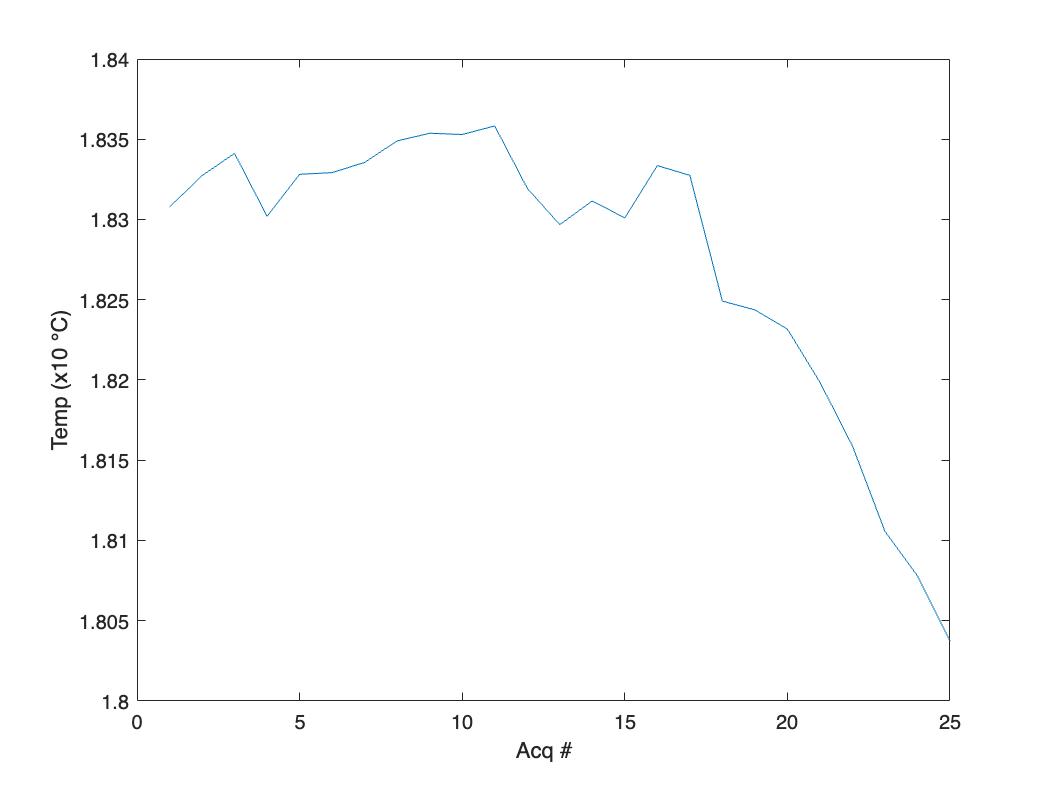

figure
plot(Temp)
ylabel('Temp (x10 ℃)')
xlabel('Acq #')

savedData = load('lifetime_collection_offset0.mat')

savedData = struct with fields:
          offset: 0
       fixoffset: 1
        Acq_nums: [33×1 double]
            lfts: [33×1 double]
    TruncEmpLfts: [33×1 double]
         photons: [33×1 double]
    photons_mean: [33×1 double]
    roiPositions: {1×33 cell}
             Acq: 23
            Acqs: [2×1 double]
          ROInum: 2


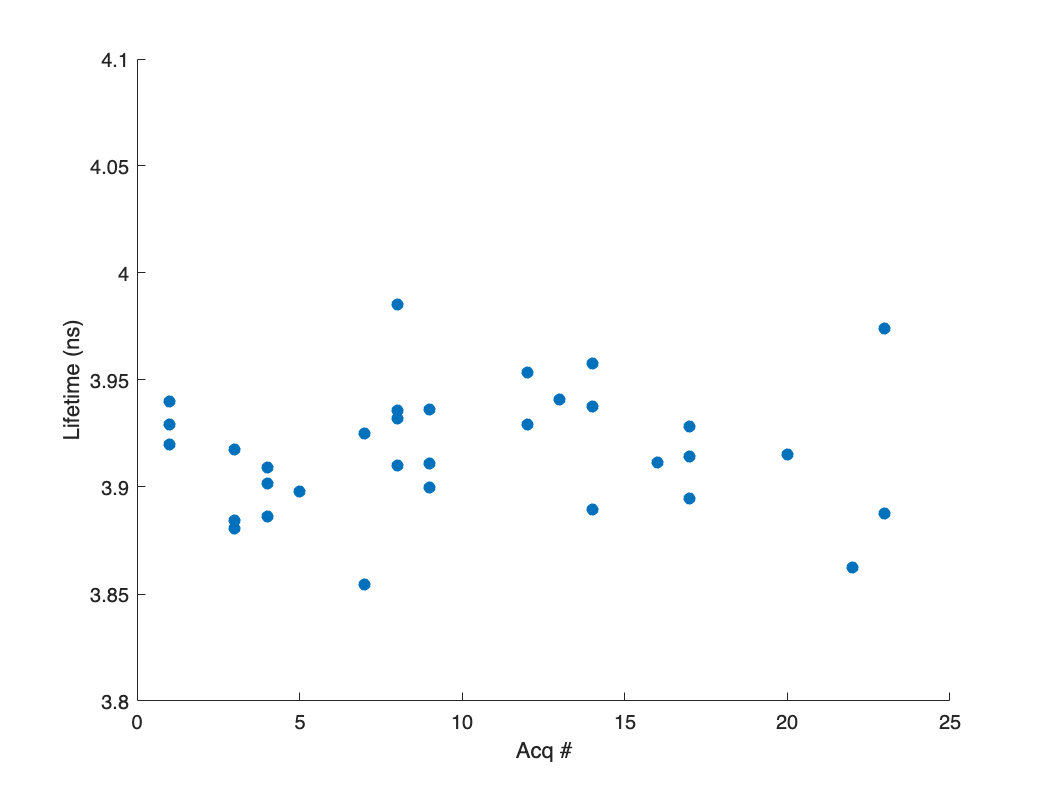

figure
scatter(savedData.Acq_nums, savedData.lfts, 'filled')
ylim([3.8 4.1])
ylabel('Lifetime (ns)')
xlabel('Acq #')